model = 'elastic_joint_param_estim';

load_system(model)

set_param(model,'SimulationCommand','disconnect')  % pulizia

slbuild(model)  % rebuild

### Generating code and artifacts to 'Model specific' folder structure
### Generating code into build folder: Z:\Documents\Control_lab\Control_repo\Lab_3\Generated_files\codegen\elastic_joint_param_estim_sldrt_win64


### Generated code for 'elastic_joint_param_estim' is up to date because no structural, parameter or code replacement library changes were found.
.
### Processing Template Makefile: C:\Program Files\MATLAB\R2024b\toolbox\sldrt\rtw\sldrt.tmf
### Makefile Z:\Documents\Control_lab\Control_repo\Lab_3\Generated_files\codegen\elastic_joint_param_estim_sldrt_win64\elastic_joint_param_estim.mk is up to date
### Building elastic_joint_param_estim: .\elastic_joint_param_estim.bat
 
Z:\Documents\Control_lab\Control_repo\Lab_3\Generated_files\codegen\elastic_joint_param_estim_sldrt_win64>set MATLAB=C:\Program Files\MATLAB\R2024b  
 
Z:\Documents\Control_lab\Control_repo\Lab_3\Generated_files\codegen\elastic_joint_param_estim_sldrt_win64>"C:\Program Files\MATLAB\R2024b\bin\win64\gmake" -f elastic_joint_param_estim.mk  EXTMODE_STATIC_ALLOC=0 EXTMODE_STATIC_ALLOC_SIZE=1000000 TMW_EXTMODE_TESTING=0 COMBINE_OUTPUT_UPDATE_FCNS=0 INCLUDE_MDL_TERMINATE_FCN=1 MULTI_INSTANCE_CODE=0 OPTS="-DTGTCONN -DEXT_MOD


set_param(model,'SimulationCommand','connect')

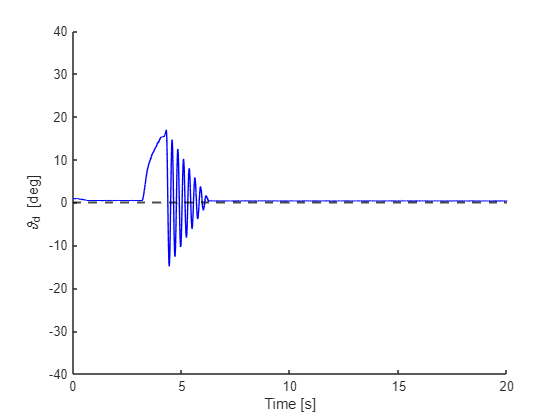

set_param(model,'SimulationCommand','start')

while ~strcmpi(status, 'stopped')
    pause(0.5);
    status = get_param(model, 'SimulationStatus');
end           


t_3_2_1 = theta_d.time;

th_d_3_2_1 = theta_d.signals.values;

figure;
hold on 
plot(t_3_2_1,th_d_3_2_1,'b');
yline(0, 'k--', 'LineWidth', 1.5);
axis([0 20 -40 40])
xlabel('Time [s]');
ylabel('\vartheta_d [deg]');
hold off


% Trova tutti picchi. Se cambi il valore di initial_beam_position devi
% cambiare anche MinPeakDistance e MinPeakHeight per avere letture pulite e
% uniche dei picchi. Verifica che i picchi siano giusti.
[pks, t_k] = findpeaks(abs(th_d_3_2_1), t_3_2_1, 'MinPeakDistance', 0.1, 'MinPeakHeight', 1);

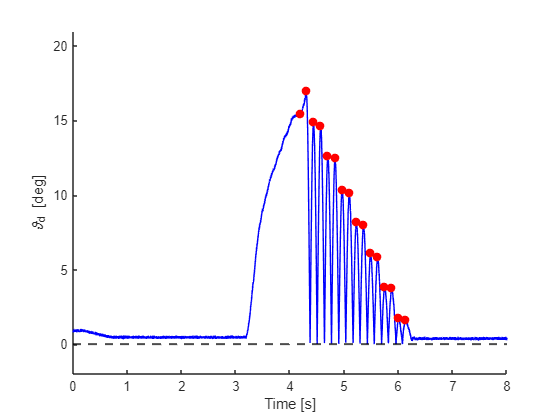


pks = pks(7:end,1);
t_k = t_k(7:end,1);
figure;
hold on 
plot(t_3_2_1,abs(th_d_3_2_1),'b');
plot(t_k, pks, 'ro', 'MarkerFaceColor', 'r');
yline(0, 'k--', 'LineWidth', 1.5);
xlim([0 8])
ylim([-2 21])
xlabel('Time [s]');
ylabel('\vartheta_d [deg]');
hold off

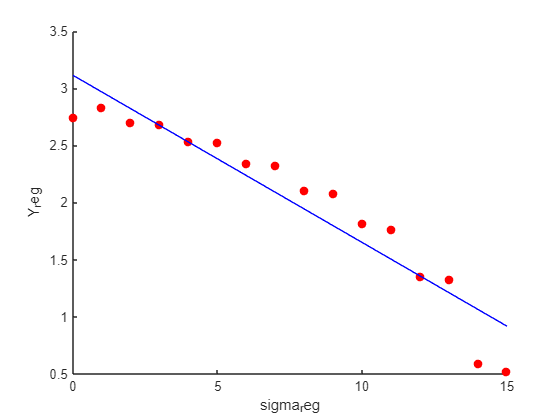


% Calcolo del decremento logaritmico 
M = length(pks);       % Numero di picchi trovati
k = (0:M-1)';          % Vettore degli indici dei picchi [0, 1, 2, ..., M-1]
z = log(abs(pks));         

sigma_reg =[-k , ones(M, 1)];

Y_reg = [z];

% tetha_LS = inv(sigma_reg' * sigma_reg) * sigma_reg'*Y_reg;
tetha_LS = sigma_reg \ Y_reg;

% Stampa retta di regressione

figure;
hold on 
plot(k, Y_reg, 'ro', 'MarkerFaceColor', 'r');
plot(k, -tetha_LS(1)*k+tetha_LS(2), 'b');
% axis([0 2 -40 40])
xlabel('sigma_reg');
ylabel('Y_reg');
hold off


% % Calcolo dello smorzamento 
xi_hat = tetha_LS(1);        % La stima del decremento logaritmico
delta_hat = xi_hat / sqrt(pi^2 + xi_hat^2);
T_k = diff(t_k);
omega_k_hat = pi ./ T_k;
omega_hat = mean(omega_k_hat);
omega_n_hat = omega_hat / sqrt(1 - delta_hat^2);
fprintf('Stima Smorzamento (delta): %.4f\n', delta_hat);

Stima Smorzamento (delta): 0.0465



fprintf('Stima Frequenza Naturale (omega_n): %.2f rad/s\n', omega_n_hat);

Stima Frequenza Naturale (omega_n): 24.43 rad/s



J_b = 1.4/1000; % Kgmq

mld.Bb = J_b*2*delta_hat*omega_n_hat;
mld.k = J_b*omega_n_hat^2;

fprintf('Beam viscous friction coefficient (B_b_hat): %.4f\n', mld.Bb);

Beam viscous friction coefficient (B_b_hat): 0.0032



fprintf('Elastic Joint stiffness (k_hat): %.2f Nm/rad\n', mld.k);

Elastic Joint stiffness (k_hat): 0.84 Nm/rad
